% Define Schwefel Function
schwefel = @(x) 418.9829 * length(x) - sum(x .* sin(sqrt(abs(x))));

% Define Rastrigin Function
rastrigin = @(x) 10 * length(x) + sum(x.^2 - 10 * cos(2 * pi * x));

% Define dimensionality
dims = [2, 10];

% Optimization Techniques
optimization_techniques = {'Genetic Algorithm', 'Particle Swarm Optimization'};

% Initialize arrays to store optimal function values
optimal_values = zeros(length(dims), length(optimization_techniques), 2);

% Loop through each dimensionality
for d_idx = 1:length(dims)
    d = dims(d_idx);
    
    % Loop through each benchmark function
    for func_idx = 1:2
        if func_idx == 1
            func = schwefel;
            func_name = 'Schwefel';
        else
            func = rastrigin;
            func_name = 'Rastrigin';
        end
        
        % Loop through each optimization technique
        for opt_idx = 1:length(optimization_techniques)
            technique = optimization_techniques{opt_idx};
            
            % Define optimization parameters
            options = optimoptions(@ga, 'Display', 'off', 'MaxGenerations', 100);
            if strcmp(technique, 'Particle Swarm Optimization')
                options = optimoptions(@particleswarm, 'Display', 'off', 'MaxIterations', 100);
            end
            
            % Define optimization parameters
            options = optimoptions(@ga, 'Display', 'off', 'MaxGenerations', 100);
            if strcmp(technique, 'Genetic Algorithm')
                [x_opt, fval] = ga(func, d, [], [], [], [], [], [], [], options);
            elseif strcmp(technique, 'Particle Swarm Optimization')
                [x_opt, fval] = particleswarm(func, d, [], [], options);
            end
            
            % Store optimal function value
            optimal_values(d_idx, opt_idx, func_idx) = fval;
        end
    end
end

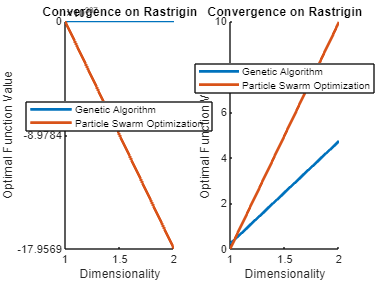


% Plot convergence curves
figure;
for func_idx = 1:2
    subplot(1, 2, func_idx);
    hold on;
    for opt_idx = 1:length(optimization_techniques)
        plot(1:size(optimal_values, 1), optimal_values(:, opt_idx, func_idx), 'LineWidth', 2);
    end
    hold off;
    title(['Convergence on ', func_name]);
    xlabel('Dimensionality');
    ylabel('Optimal Function Value');
    legend(optimization_techniques, 'Location', 'best');
end